# 1.3.12. Ускорение расчетов

**Практическое занятие**

Оптимизируйте приведенные алгоритмы и программные конструкции для ускорения расчета

## Импорт данных

a = randn(1000000,1)

a =     2.0727
   -0.1578
   -1.0709
   -3.4475
   -1.1382
   -2.3266
   -0.9606
   -0.3386
    1.3666
    0.4498


tic
for i = 1 : length(a)
    a(i) = sin(pi * a(i));
end
toc

Elapsed time is 2.089416 seconds.


tic
a = sin(pi * a);
toc

Elapsed time is 0.016630 seconds.


a = rand(500000, 2) * 10;
% a = rand(5000, 2) * 10;
scatter(a(:,1), a(:,2), '.');
b = zeros(size(a));
% b = [];
n = 0;
tic
for i = 1 : size(a, 1)
    if a(i, 2) <= a(i, 1) / 2
        n = n + 1;
        b(n, :) = a(i, :);
    end
end
toc

Elapsed time is 1.532185 seconds.


b = b(1:n, :);
n

n = 124861

S = 10*10 * n / size(a, 1)

S = 24.9722

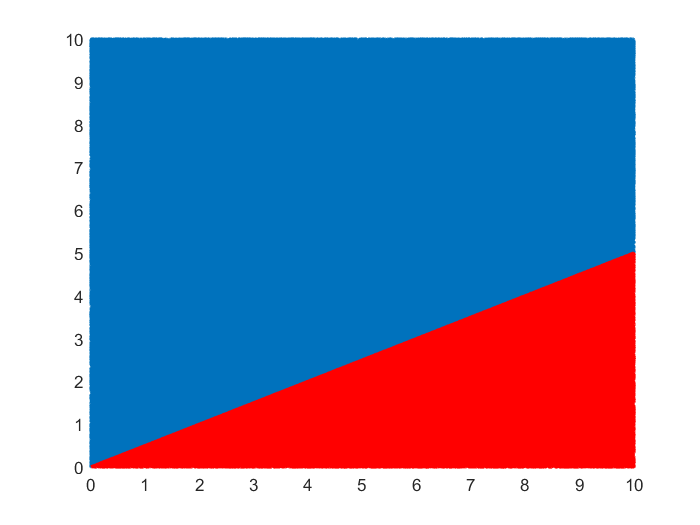

hold on
fplot(@(x) x/2, [0 10], 'r', 'LineWidth', 2)
scatter(b(:,1), b(:,2), '.r');
hold off

tic
b = a(a(:,2) <= a(:, 1) / 2, :);
n = size(b, 1)

n = 124861

S = 10*10 * n / size(a, 1)

S = 24.9722

toc

Elapsed time is 0.026411 seconds.


*2018 © ЦИТМ Экспонента*